addpath 'E:\MATLAB'
addpath 'E:'\MATLAB\Images\
ImageNames={'baby.png';'bird.png';'woman.png';'monarch.png';'airplane.png';'arctichare.png';'peppers1.tiff';'peppers2.png';'foreman.png'};
%ImageNames={'kodim01.png';'kodim02.png';'kodim03.png';'kodim04.png';'kodim05.png';'kodim06.png';'kodim07.png';'kodim08.png';'kodim09.png';'kodim10.png';'kodim11.png';'kodim12.png';'kodim13.png';'kodim14.png';'kodim15.png'};
%ImageNames={'aerial1.tiff';'aerial2.tiff';'aerial3.tiff';'aerial4.tiff';'aerial5.tiff';'aerial6.tiff';'aerial7.tiff';'aerial8.tiff';'aerial9.tiff';'aerial10.tiff'};
PSNRwith=zeros(size(ImageNames,1),1);
PSNRwithout=zeros(size(ImageNames,1),1);
SSIMwith=zeros(size(ImageNames,1),1);
SSIMwithout=zeros(size(ImageNames,1),1);
PSNRimprovement=zeros(size(ImageNames,1),1);
SSIMimprovement=zeros(size(ImageNames,1),1);
tic
for i=1:size(ImageNames,1)
    string=char(ImageNames(i));
    A=imread(string);
    B=im2double(rgb2gray(A));
    [w,witho]=KipkoechSuperResolution(B);
    PSNRwith(i)=psnr(w,B);
    PSNRwithout(i)=psnr(witho,B);
    SSIMwith(i)=ssim(w,B);
    SSIMwithout(i)=ssim(witho,B);
    PSNRimprovement(i)=PSNRwith(i)-PSNRwithout(i);
    SSIMimprovement(i)=SSIMwith(i)-SSIMwithout(i);
end
toc

Elapsed time is 13.838507 seconds.


T=table(ImageNames,PSNRwith,PSNRwithout,PSNRimprovement,SSIMwith,SSIMwithout,SSIMimprovement)

T = 9×7 table
        ImageNames        PSNRwith    PSNRwithout    PSNRimprovement    SSIMwith    SSIMwithout    SSIMimprovement
    __________________    ________    ___________    _______________    ________    ___________    _______________

    {'baby.png'      }     35.478       32.584           2.8934         0.94425       0.89974         0.044501    
    {'bird.png'      }     34.943       31.063           3.8792         0.96691       0.92094         0.045968    
    {'woman.png'     }     30.302       27.224           3.0788         0.93929       0.88787         0.051424    
    {'monarch.png'   }     31.467       28.272           3.1957         0.95332       0.91909         0.034236    
    {'airplane.png'  }     31.156       28.491           

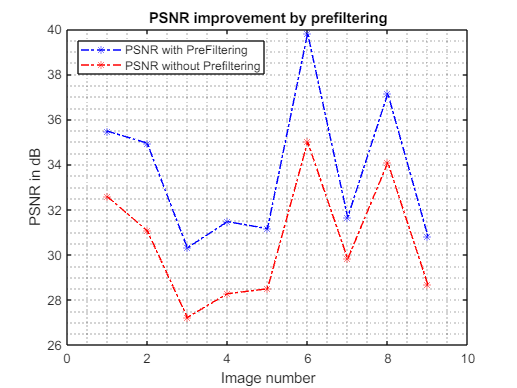

Table_location='E:\MATLAB\Results';
path_format = [Table_location '\PSNRImprovementWithPreFiltering.xlsx'];
writetable(T,path_format)
n=1:size(ImageNames,1);
N=size(ImageNames,1);
figure;
plot(n,PSNRwith,'-.b*',n,PSNRwithout,'-.r*')
xlim([0 N+1]);
grid minor
ylabel 'PSNR in dB'
xlabel 'Image number'
title ('PSNR improvement by prefiltering','FontWeight','bold');
legend('PSNR with PreFiltering','PSNR without Prefiltering',"Location","northwest")

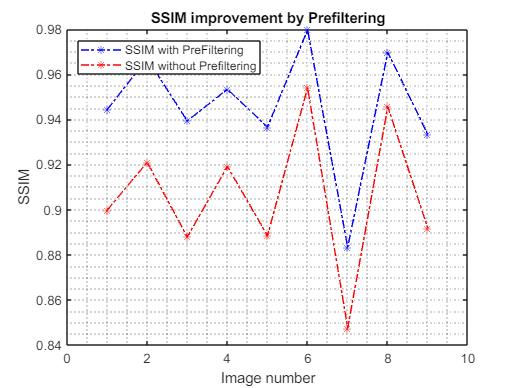

figure;
plot(n,SSIMwith,'-.b*',n,SSIMwithout,'-.r*')
xlim([0 N+1]);
grid minor
ylabel 'SSIM'
xlabel 'Image number'
title ('SSIM improvement by Prefiltering','FontWeight','bold');
legend('SSIM with PreFiltering','SSIM without Prefiltering',"Location",'northwest')

function [IR,IRW]= KipkoechSuperResolution (R)
k=2;
LR=KipkoechDownSampling(R,k);
LRPrefiltered=KipkoechCubicBSplinesPrefilter(LR);
IR=KipkoechBSplinesInterpolation(LRPrefiltered,k);
IRW=KipkoechBSplinesInterpolation(LR,k);
end